- Let $$x[n]=h[n]=(0.9)^nu[n]$$ and $y[n]=x[n]*h[n]$

(a)  Determine  analytically and plot the first 99 non-zero samples using $y[n]$ the stem function. 

-sol-

Since $H(z)=X(z)=\frac{1}{1-0.9z^{-1}}$, we have $Y(z)=\frac{1}{1-0.9z^{-1}}$ and thus $y[n]=(n+1)0.9^nu[n]$. In the inverse transform, we use the fact that $h[n]$ is casual.

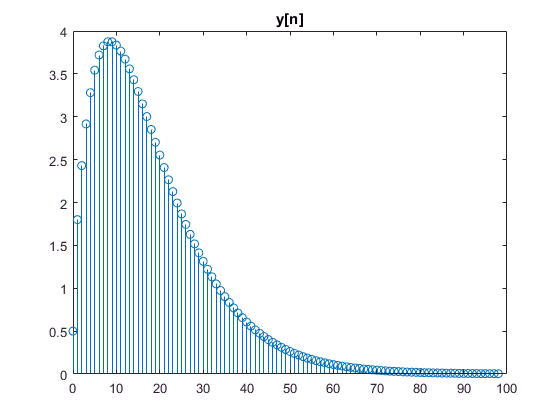

clc;clear;close all;

n=(0:98);
y=(n+1).*(0.9).^n.*heaviside(n);
stem(n, y(1:99)); title('y[n]');

(b) Take first 50 samples of $x[n]$ and $h[n]$. Compute and plot $y[n]$ using the conv function. 

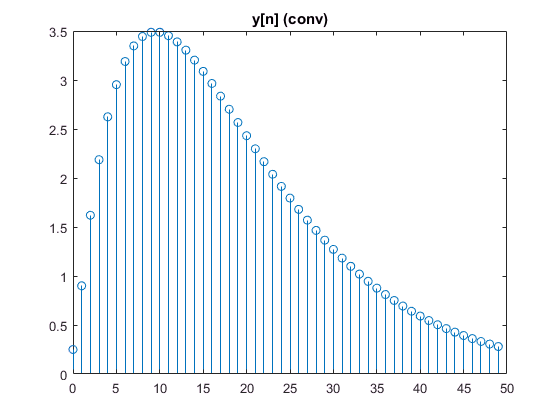

n=(0:49);
x=(0.9.^n).*heaviside(n);
y=conv(x, x);
stem(n, y(1:50)); 
title('y[n] (conv)');

(c) Using the filter function, determine and plot the first 99 samples of $y[n]$. 

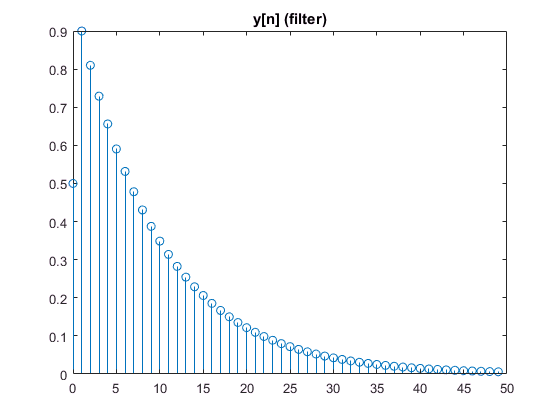

b = 1;
a = [1 -0.9];
y = filter(b,a,x,[],1);
stem(n, y(1:50)); 
title('y[n] (filter)');

(d) Which of the outputs in (b) and (c) come close to that in (a)? Explain. 

-sol-

    In the inverse transform, if we pick the wrong R.O.C., we'll have the wrong $y[n]$. Using the code below to plot (with a propriate shift).

n=(0:98)

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


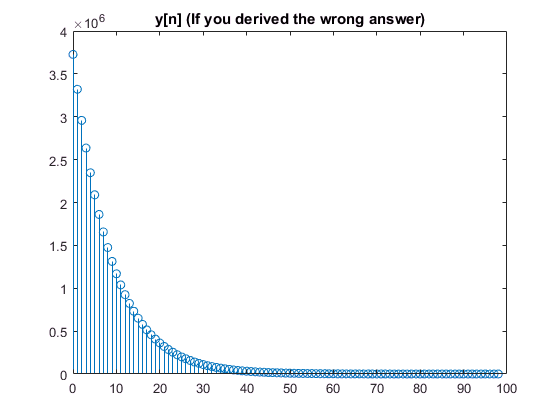

y1=-(n-100+1).*(0.9).^(n-100).*heaviside(-(n-100)-1);
stem(n, y1(1:99)); title('y[n] (If you derived the wrong answer)');

So (a) (the right answer) corresponds to conv() function, the wrong answer has a similar shape to filter() function. It's because the choice of ROC is wrong.

2. The sum $A_x=\sum_nx[n]$ can be thought of as a measure of the “area” under a sequence $x[n]$.

(a) Starting with the convolution sum (2.36), show that $A_y=A_xA_h$ (derive in the live script).


$$A_y=\sum_{n=-\infty}^{\infty}\sum_{k=-\infty}^{\infty}x[k]h[n-k]\\
=\sum_{k=-\infty}^{\infty}\sum_{n=-\infty}^{\infty}x[k]h[n-k]\\
=\sum_{k=-\infty}^{\infty}x[k]\sum_{n=-\infty}^{\infty}h[n-k]\\
=\sum_{n=-\infty}^{\infty}x[n]\sum_{n=-\infty}^{\infty}h[n\quad\text{(shift the index)}]\\
=A_xA_h$$
 

(b) Given the sequences

clc;clear;close all;

x=sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101);
h=ones(1,5);

compute $y[n] = h[n]*x[n]$, check whether $A_y=A_xA_h$, and use the subplot function plot $x[n] $ and $y[n]$ on the same graph. 

n=(0:100);
y=conv(x,h);

Ax=0;
Ah=0;
Ay=0;

for i=1:101
    Ax=Ax+x(i);
    Ay=Ay+y(i); 
end
for i=1:5
    Ah=Ah+h(i);
end

fprintf('Ax = %f\n', Ax);

Ax = -0.534492


fprintf('Ah = %f\n', Ah);

Ah = 5.000000


fprintf('Ax * Ah = %f\n', Ax*Ah);

Ax * Ah = -2.672462


fprintf('Ay = %f\n', Ay);

Ay = -1.878098


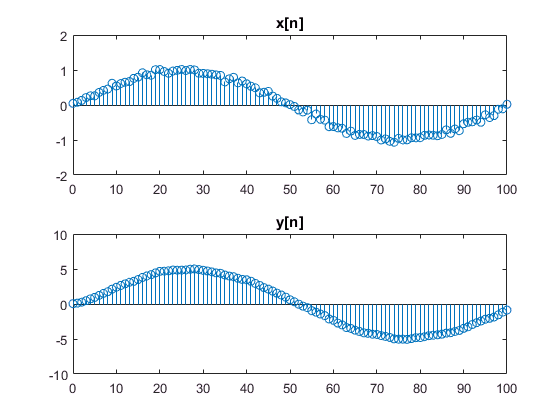


figure(1)
subplot(2,1,1)
stem(n, x(1:101))
title('x[n]')
subplot(2,1,2)
stem(n, y(1:101))
title('y[n]')

(c) Normalize $h[n]$ so that $A_h=1$ and repeat part (b). 

h = h ./ Ah

h =     0.2000    0.2000    0.2000    0.2000    0.2000



n=(0:100);
y=conv(x,h);

Ax=0;
Ah=0;
Ay=0;

for i=1:101
    Ax=Ax+x(i);
    Ay=Ay+y(i); 
end
for i=1:5
    Ah=Ah+h(i);
end

fprintf('Ax = %f\n', Ax);

Ax = -0.534492


fprintf('Ah = %f\n', Ah);

Ah = 1.000000


fprintf('Ax * Ah = %f\n', Ax*Ah);

Ax * Ah = -0.534492


fprintf('Ay = %f\n', Ay);

Ay = -0.375620


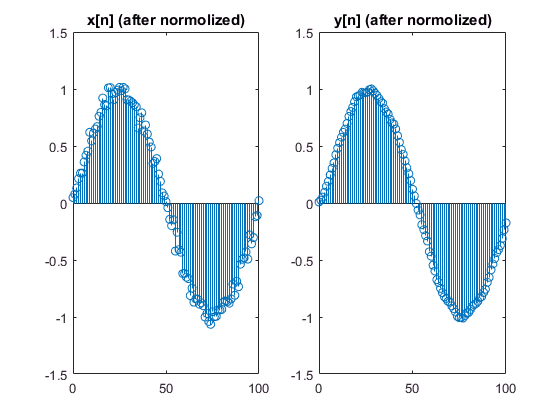


figure(2)
subplot(1,2,1)
stem(n, x(1:101))
title('x[n] (after normolized)')
subplot(1,2,2)
stem(n, y(1:101))
title('y[n] (after normolized)')

(d) If  $A_h$ = 1, then$A_y=A_x$. Use this result to explain  Use this result to explain the difference between the plots obtained in parts (b) and (c). 

 -sol-

    I think it just want to tell us that the convolution has a scaler-product property, i.e., $x*(ah)=a(x*h)$

3. The response of a LTI system to the input $$x[n]=u[n]$$ is $y[n] = 2\cdot\big(\frac{1}{3}\big)^nu[n]. $

(a) Find the impulse response $h[n]$ of the system, and check the results using the function filter.

-sol-

Since $X(z)=\frac{1}{1-z^{-1}}$ and $Y(z)=\frac{2}{1-\frac{1}{3}z^{-1}}$, we have,


$$H(z)=\frac{Y(z)}{X(z)}
=\frac{2(1-z^{-1})}{1-\frac{1}{3}z^{-1}}
=6-\frac{4}{1-\frac{1}{3}x}
$$


and thus $h[n]=6\delta[n]-4\big(\frac{1}{3}\big)^n$

clc;clear;close all;

n=(0:29);
x=heaviside(n);
h=-4*(1/3).^n

h =    -4.0000   -1.3333   -0.4444   -0.1481   -0.0494   -0.0165   -0.0055   -0.0018   -0.0006   -0.0002   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


h(1)=2    % Assign h(1)=2 since the delta function

h =     2.0000   -1.3333   -0.4444   -0.1481   -0.0494   -0.0165   -0.0055   -0.0018   -0.0006   -0.0002   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000



y=2*(1/3).^n.*x

y =     1.0000    0.6667    0.2222    0.0741    0.0247    0.0082    0.0027    0.0009    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


y1 = filter(x,1,h);

figure(3)
subplot(2,1,1)
stem(n, y(1:30))
title('y[n] (direct compute')
subplot(2,1,2)
stem(n, y1(1:30))
title('y[n] (filter)')

(b) Plot the pole-zero pattern using the function zplane(b, a).

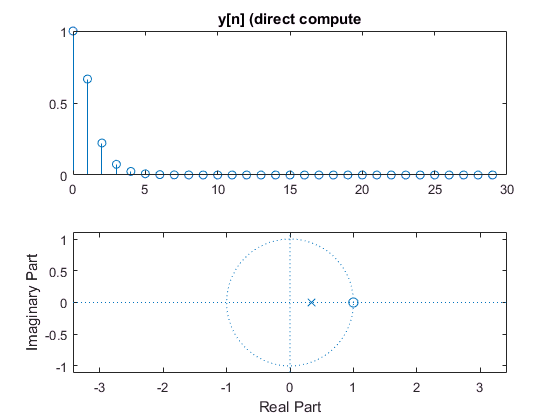

b=[2, -2];
a=[1, -0.333];
zplane(b, a)

(c) Compute and plot the impulse response using the functions filter and stem. Compare with the plot obtained using the function impz. 

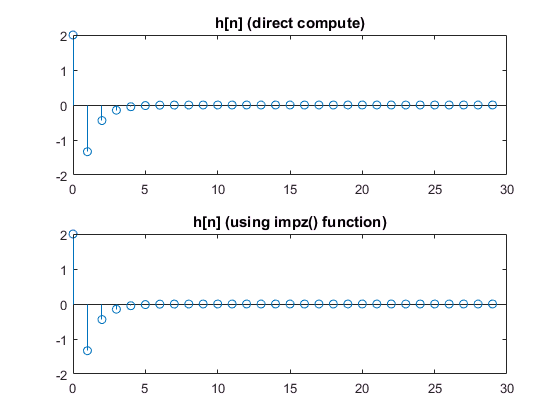

figure(4)
subplot(2,1,1)
stem(n, h)
title('h[n] (direct compute)')
subplot(2,1,2)
h1=impz(b, a, 30);
stem(n, h1)
title('h[n] (using impz() function)')

  So two of them are totally same.

(d) Use the function residuez and the z-transform pairs in Table 3.1 to find an analytical expression for the impulse response h[n].

-sol-

  Analytical expression for h[n] has derived in (a). Use residuez() to check the consistency.

[A,p,C]=residuez(b,a)

A = -4.0060

p = 0.3330

C = 6.0060

4. Find the impulse response of the system (3.97) for the case of real and equal poles and use the result to determine how the location of the poles affects

(a) the stability of the system 

(b) the shape of the impulse response. 

(Hint: Use MATLAB to replicate Figure 3.10 for a double pole, find C and discuss stability of the three cases $|a_1|<C, |a_2|=C, |a_3|>C$

-sol-

  Real and equal poles implies $a_1^2=4a_2$, so

 
$$H(z)=\frac{z(b_0z+b_1)}{z^2+a_1z+\frac{a_1^2}{4}}
=\frac{z(b_0z+b_1)}{\big(z+\frac{a_1}{2}\big)^2}$$


and the condition for convergence:


$$\bigg|-\frac{a_1}{2}\bigg|<1$$


Thus $|a_1|<2=C$. Moreover, we derived $h[n]=\big(\frac{a_1}{2}\big)^nu[n]$. To be more precisely, we plot some possible value of $a_1$ with R.O.C. of $H(z)$ in the following diagram.

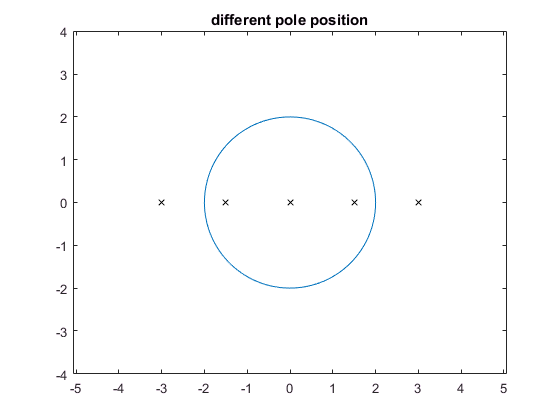

clc;clear;close all;

t=0:pi/100:2*pi;
x=2*sin(t);
y=2*cos(t);

figure(6)
plot(x,y)
hold on;
plot([-3,-1.5,0,1.5, 3],zeros(5),'xk')
axis([-4,4,-4,4]);
axis equal;
title('different pole position')

Case 1: $|a_1|<2$, the system is stable

figure(7)
subplot(3,1,1)
a1=1.5;
n=(0:20);
h=(a1/2).^n.*heaviside(n)*2;
stem(n,h)
title('h[n]: a1=1.5')

Case 2: $|a_1|=2$, the system is unstable.

subplot(3,1,2)
a1=2;
n=(0:20);
h=(a1/2).^n.*heaviside(n)*2;
stem(n,h)
title('h[n]: a1=2')

Case 3: $|a_1|>2$, the system is umstable.

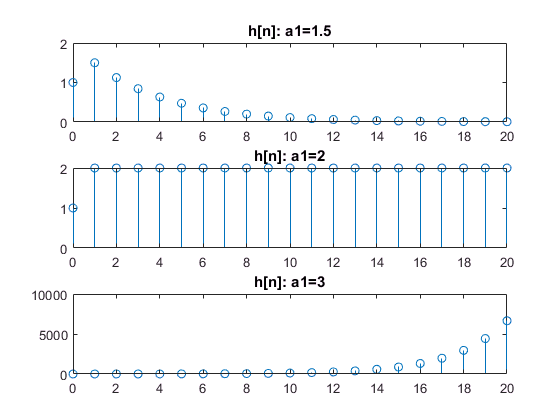

subplot(3,1,3)
a1=3;
n=(0:20);
h=(a1/2).^n.*heaviside(n)*2;
stem(n,h)
title('h[n]: a1=3')

5. Consider the following LCCDE: $y[n]=2\cos(\omega_0)y[n-1]-y[n-2]$, with no input but with initial conditions $y[-1]=0$ and $y[-2]=-A\sin(\omega_0)$

(a) Show that the solution of the above LCCDE is given by the sequence $y[n]=A\sin[(n+1)\omega_0]u[n]$. This system is known as a digital oscillator (derive in the live script). 

-sol-

  Using the given formula, we obtain $Y^+(z)=\frac{A\sin(\omega_0)}{1-2\cos\omega_0z^{-1}+z^{-2}}$.  

  By time shifting property of one-sided Z-transform, say $Y^+(y[n-1])=y[-1]+z^{-1}Y^+(z)$, and since $y[-1]=0$, we have $y[n]=A\sin((n+1)\omega_0)u[n].$

(b) For $A=2$ and $\omega_0=0.1\pi$, verify the operation of the above digital oscillator, using the filtic and the filter function. 

(Hint: Check one-sided z-transform in supplement) 

clc;clear;close all;

A=2;
omega0=0.1*pi;

n=(0:19);
b = [0 0 0]; 
a = [1 -2*omega0 1]; 
yic = [0 -A*sin(omega0)]; 
xic = [0 0]; 

zic = filtic(b, a, yic, xic);
y = filter(b, a, x, zic);

zic

zic =     0.6180         0


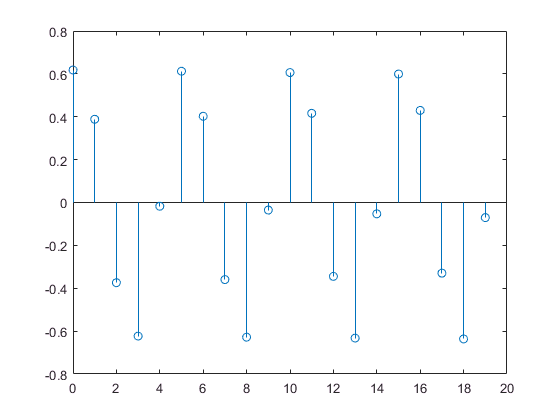

figure(8)
stem(n,y(1:20))

title('y[n]')

6. In this problem we illustrate the numerical evaluation of DTFS using MATLAB. 

(a) Write a function c=dtfs0(x) which computes the DTFS coefficients (4.67) of a periodic signal and verify the result with dtfs function. 

clc;clear;close all;

a = [1 2 3];
c = dtfs0(a)

c =    2.0000 + 0.0000i
  -0.5000 + 0.2887i
  -0.5000 - 0.2887i


ans =    2.0000 + 0.0000i  -0.5000 + 0.2887i  -0.5000 - 0.2887i


(b) Write a function x=idtfs0(c) which computes the inverse DTFS (4.63) and verify the result with idtfs function. 

idtfs0(c) 

ans =    1.0000 - 0.0000i   2.0000 - 0.0000i   3.0000 + 0.0000i


7. (12%) Determine and plot the magnitude and phase spectra of the following periodic sequences: 

(a) $x_1[n] = 4\cos(1.2\pi n+ 3\pi) + 6\sin(0.4\pi n −6\pi)$ 

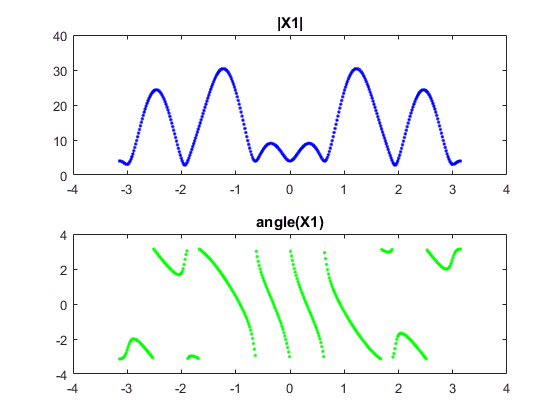

clc;clear;close all;
om=linspace(-pi, pi, 360);

n = 0:10;
x1=4*cos(1.2*pi*n+3*pi)+6*sin(0.4*pi*n-6*pi);

X1=freqz(x1, 1, om);
X1_mag = abs(X1);
X1_phase = angle(X1);

figure(10)
subplot(2,1,1)
plot(om, X1_mag, '.b')
title('|X1|')
subplot(2,1,2)
plot(om, X1_phase, '.g')
title('angle(X1)')

(b) $x_2[n] = \{1,1,0,1,1,1,0,1\}$, (one period) 

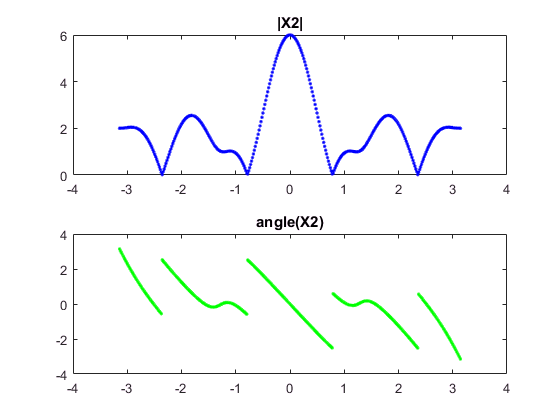

x2=[1 1 0 1 1 1 0 1];

X2=freqz(x2, 1, om);
X2_mag = abs(X2);
X2_phase = angle(X2);

figure(11)
subplot(2,1,1)
plot(om, X2_mag, '.b')
title('|X2|')
subplot(2,1,2)
plot(om, X2_phase, '.g')
title('angle(X2)')

(c) $x_3[n] = 1 − \sin(\frac{n\pi}{4}),\quad0 ≤ n ≤ 11$ (one period) 

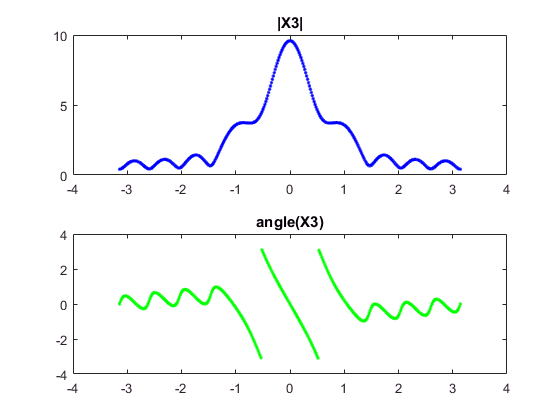

n = 0:11;
x3=1-sin(n.*pi/4);

X3=freqz(x3, 1, om);
X3_mag = abs(X3);
X3_phase = angle(X3);

figure(12)
subplot(2,1,1)
plot(om, X3_mag, '.b')
title('|X3|')
subplot(2,1,2)
plot(om, X3_phase, '.g')
title('angle(X3)')

8. Consider a noncausal finite length sequence $x[n] = \delta[n + 1] + \delta[n] + \delta[n − 1]$, we can compute the DTFT in MATLAB using following scripts: 

x=[1 1 1]; % n=-1,0,1 
om=linspace(-pi, pi, 60); 
X1=dtft12(x, -1, om); 
X2=freqz(x, 1, om);

 (a) Use subplot to plot the magnitude $|X_1|$, $|X_2|$ and phase $∠X_1$, $∠X_2$ in one graph respectively. 

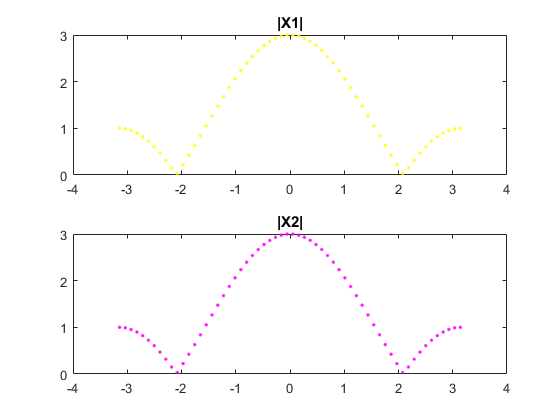

X1_mag = abs(X1);
X2_mag = abs(X2);
X1_phase = angle(X1);
X2_phase = angle(X2);

figure(13)
subplot(2,1,1)
plot(om, X1_mag, '.y')
title('|X1|')
subplot(2,1,2)
plot(om, X2_mag, '.m')
title('|X2|')

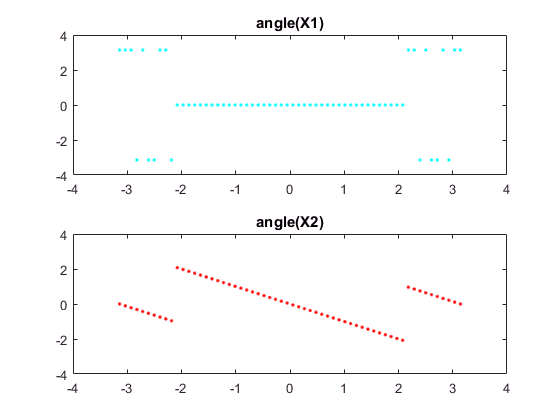


figure(14)
subplot(2,1,1)
plot(om, X1_phase, '.c')
title('angle(X1)')
subplot(2,1,2)
plot(om, X2_phase, '.r')
title('angle(X2)')

(b) Is the magnitude $|X_1|=|X_2|$? Is the phase $ ∠X_1=∠X_2$ ? If not, Explain. 

-sol-

  The function freqz() assumes the index of first term of $x$ is 0, while dtftl2() accept negative index of first term. Furthermore, since angle() function evaluate $∠X=\arctan\frac{X_I(e^{j\omega})}{X_R(e^{j\omega})}$, 


$$∠X_1=∠(1+e^{-j\omega}+e^{j\omega})=∠(1+2\cos\omega)=\pm\omega$$


We may change the sign of $\omega$ when crossing zeros of $|X_1|$. Analogously, we apply equation (4.136) on $X_2$,


$$∠X_2=∠(1+e^{-j\omega}+e^{-j2\omega})=∠\frac{1-e^{-j2\omega}}{1-e^{-j\omega}}=∠1-\frac{\omega}{2}+\pi=-\frac{\omega}{2}\pm\pi$$


We may change the sign of $\pi$ when crossing zeros of $|X_2|$. Both of these change were taken with an eye to maintain the odd-symmetry property since angle() limited the phase in $(-\pi,\pi)$.

9.  In this problem use the image file “DSP.png” which has 100×300 pixels (unsigned 8 bits per pixel). You can use the following MATLAB script to load, show and store the image files:  

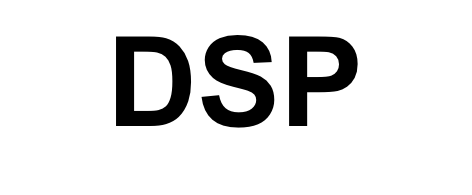

img = imread('DSP.png'); 
imshow(img);

(a) Consider the 5×5 impulse response h[m, n] given as follow: 


$$h[m,n]=
    \left\{\begin{array}{ll} 
   1/25, & -2\leq m,n\leq2 \\
    0, & \text{Otherwise}
    \end{array}\right. $$


filter the “DSP.png” using (2.78) and display the resulting image, comment on the result. (Hint: 

You can directly use conv2 function, and make sure the data format is double before filtering)

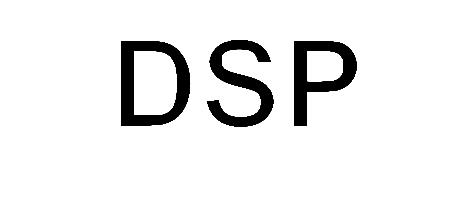

h=zeros(5);
h(:,:)=0.04;
img_new=conv2(img, h);
imshow(img_new);

imwrite(img_new, 'DSP0.png'); 

(b) Repeat part (a) and try two different kernels $h_1[m,n]$ and$h_2[m,n]$: (known as Sobel filter) 


$$h_1[m,n]={
\left[ \begin{array}{ccc}
1 & 0 & -1\\
2 & 0 & -2\\
1 & 0 & -1
\end{array} 
\right ]}$$



$$h_1[m,n]={
\left[ \begin{array}{ccc}
1 & 2 & 1\\
0 & 0 & 0\\
-1 & -2 & -1
\end{array} 
\right ]},$$
 

what is the difference between the two results? (Hint: You should do abs and uint8 before imshow)

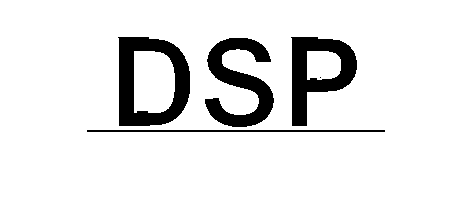

h1=[1 0 1; 2 0 -2; 1 0 -1];
h2=[1 2 1; 0 0 0; -1 -2 -1];

img_h1=conv2(img, h1);
for i = 1:102
    for j = 1:302
        img_h1(i,j)=abs(img_h1(i,j));
        img_h1(i,j)=uint8(img_h1(i,j));
    end
end
imshow(img_h1);

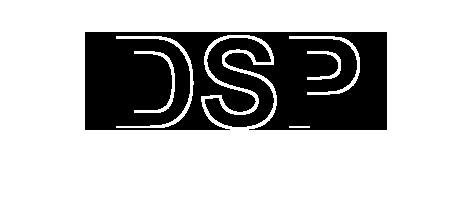

imwrite(img_h1, 'DSP_h1.png');

img_h2=conv2(img, h2);
for i = 1:102
    for j = 1:302
        img_h2(i,j)=abs(img_h2(i,j));
        img_h2(i,j)=uint8(img_h2(i,j));
    end
end
imshow(img_h2);

imwrite(img_h2, 'DSP_h2.png');

 (c) Repeat (b) by using filter2 function, what is the difference between the two functions? (Hint: Check the pixel values before abs) 

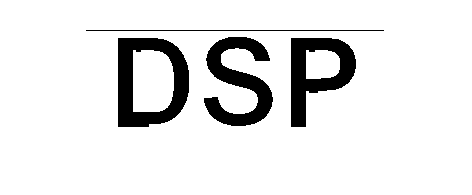

img_h1f=filter2(h1, img);
for i = 1:100
    for j = 1:300
        img_h1f(i,j)=abs(img_h1f(i,j));
        img_h1f(i,j)=uint8(img_h1f(i,j));
    end
end
imshow(img_h1f);

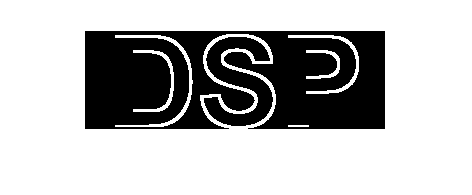

imwrite(img_h1f, 'DSP_h1f.png');

img_h2f=filter2(h2, img);
for i = 1:100
    for j = 1:300
        img_h2f(i,j)=abs(img_h2f(i,j));
        img_h2f(i,j)=uint8(img_h2f(i,j));
    end
end
imshow(img_h2f);

imwrite(img_h2f, 'DSP_h2f.png');

10.  This problem uses the sound file “handel.wav” available in MATLAB. This sound is sampled at $F_s = 8192$ samples per second using 8-bits per sample. You can use the following MATLAB script to load, play and store the audio files: 

[y,Fs] = audioread('handel.wav'); 
playerObj = audioplayer(y, Fs); 
%play(playerObj); 
%audiowrite('handel0.wav', y, Fs); 

(a) Select every other sample in audio signal y which reduces the sampling rate by a factor of two. Now listen to the new sound array using the sound function at half the sampling rate. (Hint: You can use the logical array to index array elements) 

y1=y(2:2:end,:);

y1 =    -0.0062
   -0.0312
    0.0381
   -0.0250
   -0.0750
   -0.1443
   -0.1905
   -0.0127
   -0.0750
    0.0750


playerObj = audioplayer(y1, Fs/2); 
play(playerObj); 
audiowrite('handel1.wav', y1, Fs/2); 

(b) Select every fourth sample in audio signal y which reduces the sampling rate by a factor of four. Listen to the resulting sound array using the sound function at quarter the sampling rate. 

y1=y(4:4:end,:);

y1 =    -0.0312
   -0.0250
   -0.1443
   -0.0127
    0.0750
    0.1258
   -0.0627
   -0.0189
   -0.0750
    0.0250


playerObj = audioplayer(y1, Fs/4); 
play(playerObj); 
audiowrite('handel2.wav', y1, Fs/4); 

(c) From the results of (a) and (b), what do you discover? 

-sol-

    While the sampling rate decreases, the music sounds fuzzier.